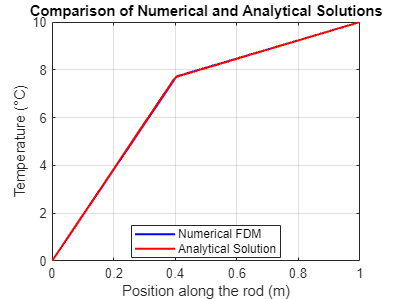

% Number of grid points and domain specifications
N = 100;                 % Total number of grid points
L = 1;                   % Length of the rod
x = linspace(0, L, N)';  % Spatial grid
dx = x(2) - x(1);        % Grid spacing

% Thermal conductivities
k1 = 1;                  % Thermal conductivity in the first segment
k2 = 5;                  % Thermal conductivity in the second segment
a = 0.4;                 % Location of discontinuity

% Initialize the temperature vector
T = zeros(N, 1);

% Boundary conditions
T(1) = 0;                % Temperature at x=0
T(N) = 10;               % Temperature at x=L (T0)

% Assemble the coefficient matrix A
A = zeros(N, N);
for i = 2:N-1
    if x(i) <= a
        k = k1;
    else
        k = k2;
    end
    A(i, i-1) = k;
    A(i, i) = -2*k;
    A(i, i+1) = k;
end

% Adjust for thermal conductivity discontinuity at 'a'
index = round(a / L * (N-1)) + 1;  % Index at discontinuity
A(index, index-1) = k1;            % Applying k1 on the left side of the discontinuity
A(index, index) = -(k1 + k2);      % Sum of both conductivities at the node
A(index, index+1) = k2;            % Applying k2 on the right side of the discontinuity

% Apply Dirichlet boundary conditions
A(1, :) = 0; A(1, 1) = 1;          % First row for the left boundary
A(N, :) = 0; A(N, N) = 1;          % Last row for the right boundary

% Solve the system of equations
T = A \ T;  
C3 = 50 / 13;
C1 = 5 * C3;
T_analytic = zeros(N, 1);
for i = 1:N
    if x(i) <= a
        T_analytic(i) = C1 * x(i);
    else
        T_analytic(i) = C3 * x(i) + 80 / 13;
    end
end
% Plotting both numerical and analytical solutions
figure;
plot(x, T, 'b', 'LineWidth', 1.5);
hold on;
plot(x, T_analytic, 'r', 'LineWidth', 1.5);
title('Comparison of Numerical and Analytical Solutions');
xlabel('Position along the rod (m)');
ylabel('Temperature (°C)');
legend('Numerical FDM', 'Analytical Solution', 'Location', 'best');
grid on;